close all
clc
syms t n
A=[0 1 2];
f=[t -t+2];
 
f=sym(f);
T=max(A)-min(A);
wo=2*pi/T;
 
Ao=0;
for i=1:length(f)
    Ao=Ao+int(f(i),'t',A(i),A(i+1));
end
Ao=simplify(Ao/(T));
 
An=0;
for i=1:length(f)
    An=An+int(f(i)*cos(n*wo*t),A(i),A(i+1));
end
An=simplify(2*An/T);
 
Bn=0;
for i=1:length(f)
    Bn=Bn+int(f(i)*sin(n*wo*t),A(i),A(i+1));
end
Bn=simplify(2*Bn/T);
 
An = char(An);
Bn = char(Bn);
An = simplify(str2sym(strrep(char(An),'sin(pi*n)','0')));
Bn=simplify(str2sym(strrep(char(Bn),'sin(pi*n)','0')));
An = simplify(str2sym(strrep(char(An),'cos(pi*n)','(-1)^n')));
Bn=simplify(str2sym(strrep(char(Bn),'cos(pi*n)','(-1)^n')));
An=simplify(str2sym(strrep(char(An),'sin(2*pi*n)','0')));
Bn=simplify(str2sym(strrep(char(Bn),'sin(2*pi*n)','0')));
An=simplify(str2sym(strrep(char(An),'cos(2*pi*n)','1')));
Bn=simplify(str2sym(strrep(char(Bn),'cos(2*pi*n)','1')));
 
disp('Ao')

Ao


pretty(Ao)

1
-
2



disp('An')

An


pretty(An)

  cos(pi n) (cos(pi n) - 1) 2
- ---------------------------
              2   2
             n  pi



disp('Bn')

Bn


pretty(Bn)

sin(pi n) 2 - sin(2 pi n)
-------------------------
           2   2
          n  pi



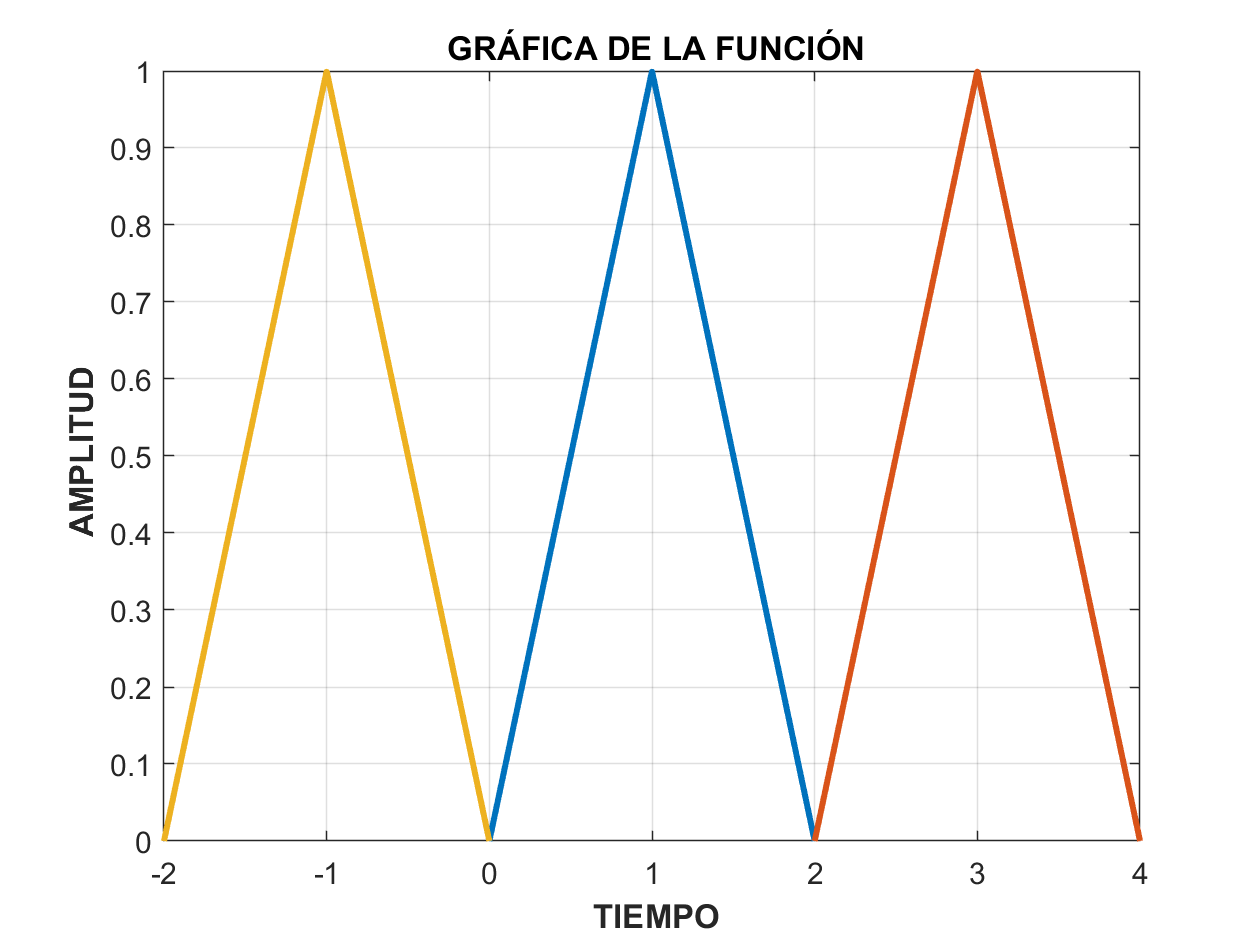

 
x=linspace(min(A),max(A),1000);
fx=0;
for i=1:length(A)-1
    if mod(i,2)==1
        fx=fx+((x>=A(i))&(x<=A(i+1))).*subs(f(i),x);
    else
        fx=fx+((x>A(i))&(x<A(i+1))).*subs(f(i),x);
    end
end
plot(x,fx,'Linewidth',2); hold on
plot(x+max(x)-min(x),fx,'Linewidth',2)
plot(x-max(x)+min(x),fx,'Linewidth',2)
plot([max(x) max(x)],[fx(1) fx(end)],'Linewidth',2)
plot([min(x) min(x)],[fx(end) fx(1)],'Linewidth',2)
grid on
xlabel('\bf TIEMPO');
ylabel('\bf AMPLITUD');
title('\bf GRÁFICA DE LA FUNCIÓN');